The goal here is to process the "liquidVideo.mp4" and calculate the height of the liquid in each frame

vLiq = VideoReader("liquidVideo.mp4")

vLiq =   VideoReader with properties:

   General Properties:
            Name: 'liquidVideo.mp4'
            Path: 'C:\Users\21692\Desktop\coursera\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 120
          Height: 216
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


The first step would be to isolate the  liquid using the background subtraction method. Therefore, we need to define a background frame to use.

After viewing the video, we can see that the first frame is a perfect match for the background. Let's extract it.

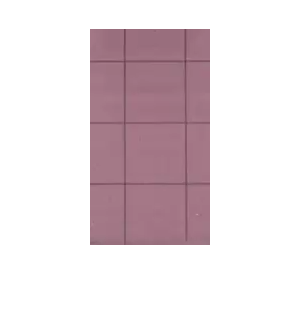

bg = read(vLiq,1);
imshow(bg)

Now let's test the background substraction using some frames.

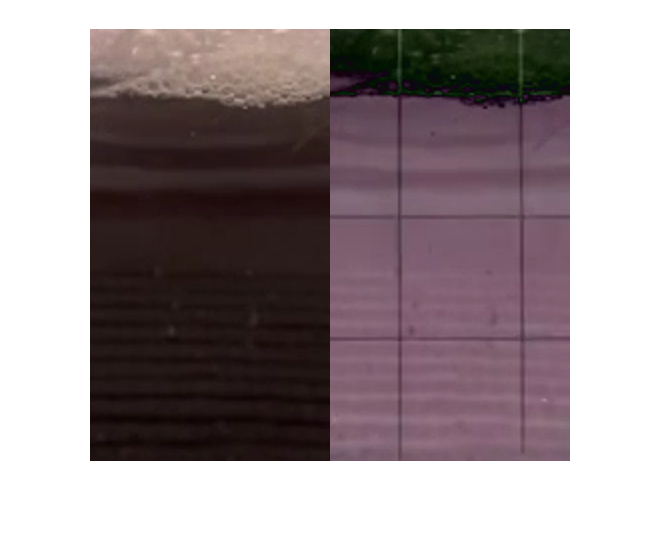

frame_175 = read(vLiq,199);
frame_175 = im2double(frame_175);
bg = im2double(bg);
substracted = abs(frame_175 - bg);
montage({frame_175,substracted})

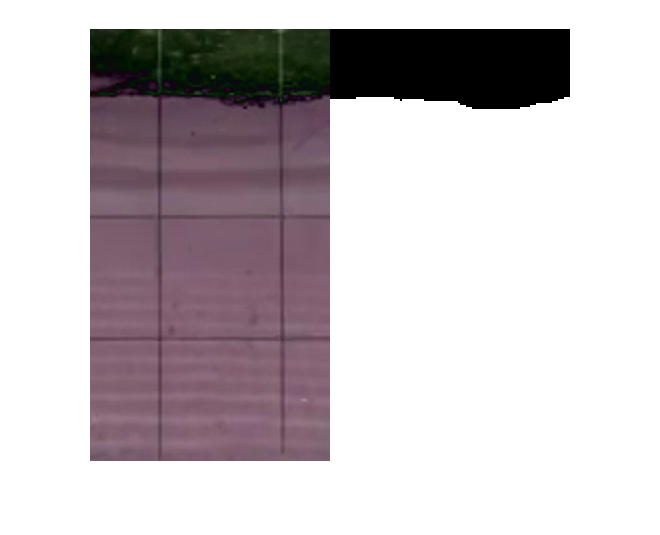

[BW_175,maskedImage_175] = SegmentLiquid(substracted);
BW_175 = ~BW_175;
montage({substracted,BW_175})

props = regionprops(BW_175,"Area")

props = struct with fields:
    Area: 21533


fractionTruePixels = props.Area/ numel(BW_175) *100

fractionTruePixels = 83.0748

Now let's test the segmentation step

numFrames_vLiq = vLiq.NumFrames;
v_seg= VideoWriter("BinaryCombined-fig","MPEG-4");

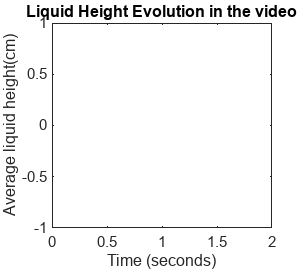

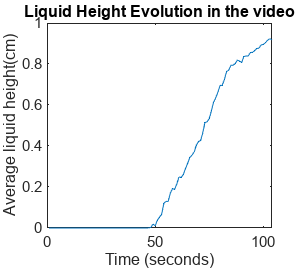

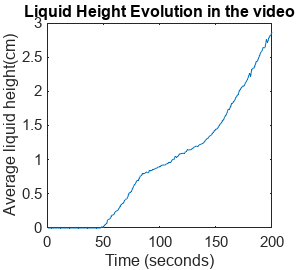

Error using imfuse>parse_inputs
The value of 'method' is invalid. Expected METHOD to
match one of these values:

'falsecolor', 'diff', 'blend', 'montage', 'checkerboard'

The input did not match any of the valid values.

Error in imfuse (line 118)
[A,B,RA,RB,method,options] = parse_inputs(varargin{:});

Caused by:
    Error using validatestring>checkString
    Expected input to be one of these types:

    char, string

    Instead its type was uint8.

v_seg.FrameRate = vLiq.FrameRate;
open(v_seg);
heights =[];
for i = 1 : numFrames_vLiq
    frame = read(vLiq,i);
    frame_bg = abs(im2double(frame) - bg);
    [BW,maskedImage] = SegmentLiquid(frame_bg);
    BW = ~BW;

    % Calculate the height of the liquid in pixels
    liquidPixels = sum(BW(:));
    liquidHeightPixels = liquidPixels / size(BW, 2);
    conversionFactor = 3.4 / size(BW, 1); % pixels per cm
    liquidHeightCm = liquidHeightPixels * conversionFactor;
    avgLiquidHeightCm = mean(liquidHeightCm);
    heights = [heights ; avgLiquidHeightCm];

    y = heights;
    x = 1 : length(y);
    
    fig = figure();
    
    % Set size of figure
    fig.Position(3) = 216; % width
    fig.Position(4) = 240; % height
    
    % Create plot
    plot(x, y);
    
    % Add title and axis labels
    title('Liquid Height Evolution in the video');
    xlabel('Time (seconds)');
    ylabel('Average liquid height(cm)');

    f = getframe(gcf); % gcf = current figure handle
    figure_data = frame2im(f);
    BW_rgb = repmat(BW,[1 1 3]);
    img = imfuse(frame,BW_rgb,"montage");
    img = imfuse(img,figure_data,"montage");
    writeVideo(v_seg,img);


end

close(v_seg);
hTable = table(heights)

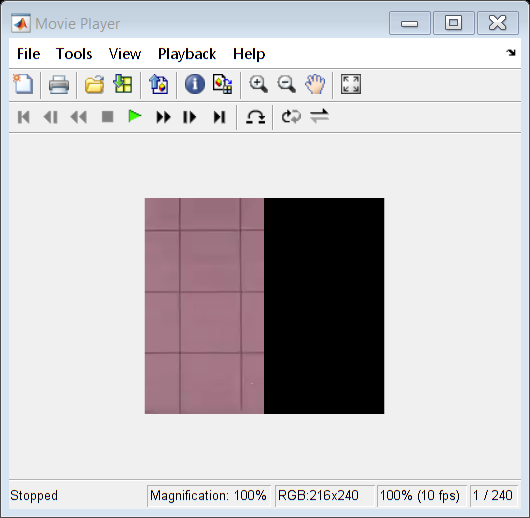

implay("BinaryCombined.mp4")

Now we want to calcuate, assuming that each frame of the video is 3.4 cm in height, the average height of the liquid 16.7 seconds into the video.

we need to first determine the corresponding frame number at that time.

framerate = vLiq.FrameRate;
frameNumber = round(framerate * 16.7)

frameNumber = 167

Next, we need to extract the mask for the liquid from the corresponding frame and calculate the height of the liquid in pixels:

vLiq.CurrentTime = 16.7;
frame_desired = readFrame(vLiq);
frame_desired_bg = abs(im2double(frame_desired) - bg);
[BW_current,maskedImage_current] = SegmentLiquid(frame_desired_bg);
BW_current = ~BW_current;
% Calculate the height of the liquid in pixels
liquidPixels = sum(BW_current(:));
liquidHeightPixels = liquidPixels / size(BW_current, 2);

Finally, we can convert the height of the liquid in pixels to centimeters using the conversion factor:

conversionFactor = 3.4 / size(BW_current, 1); % pixels per cm
liquidHeightCm = liquidHeightPixels * conversionFactor;

The average height of the liquid 16.7 seconds into the video is the height of the liquid in centimeters averaged over all columns:

avgLiquidHeightCm = mean(liquidHeightCm)

avgLiquidHeightCm = 1.8743

## The liquid height's evolution over the entire video

Let's now take a look at the evolution of the liquid height over the entire video using the value of the hTable variable

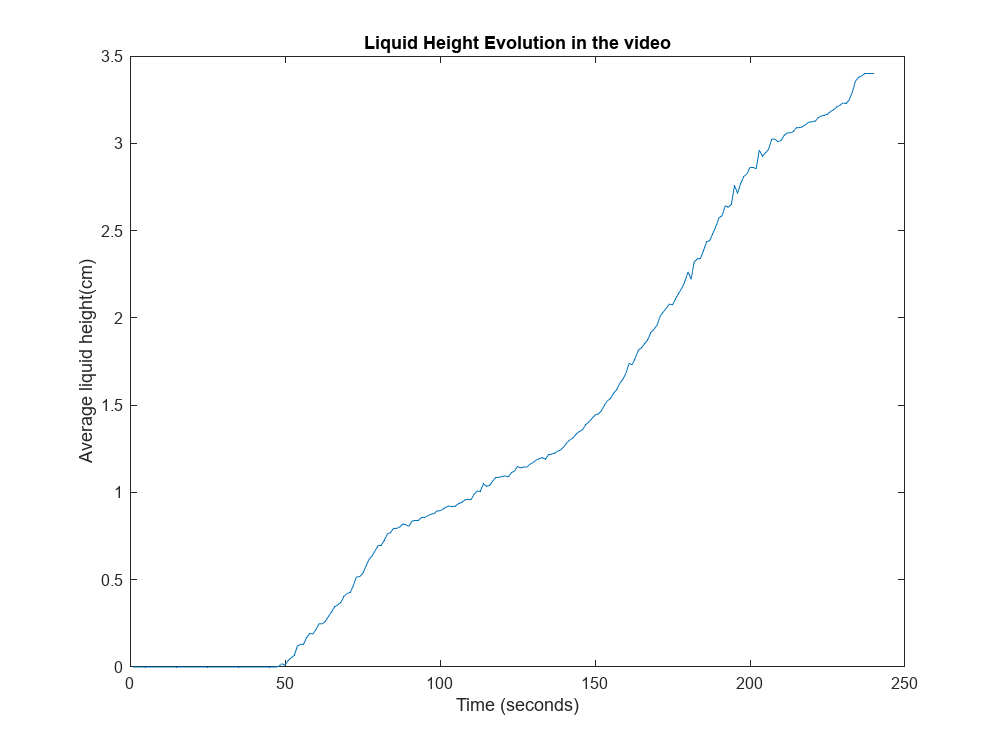

y = hTable.heights;
x = 1 : length(y);

fig = figure();

% Set size of figure
fig.Position(3) = 800; % width
fig.Position(4) = 600; % height

% Create plot
plot(x, y);

% Add title and axis labels
title('Liquid Height Evolution in the video');
xlabel('Time (seconds)');
ylabel('Average liquid height(cm)');
saveas(gcf, 'LiquidHeightEvolution.png');